### 
$$I(t) = \alpha exp(-t/\tau)$$


%fit single exponential decay to normalized photon count data

time = linspace(0, 100, 2000); %2000 time points from 0 to 100 ns
I = exp(-time / 5) + 0.02 * randn(size(time)); %simulate decay + noise
I = I / max(I); %normalize to start at 1

%known fixed lifetime
tau1 = 5; %ns

%exponential model (fit amplitude only)
model = @(params, t) params(1) * exp(-t / tau1);

%initial guess for amplitude
initial_guess_ls = [1];

%least squares fit
[params_ls, res] = lsqcurvefit(model, initial_guess_ls, time, I);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


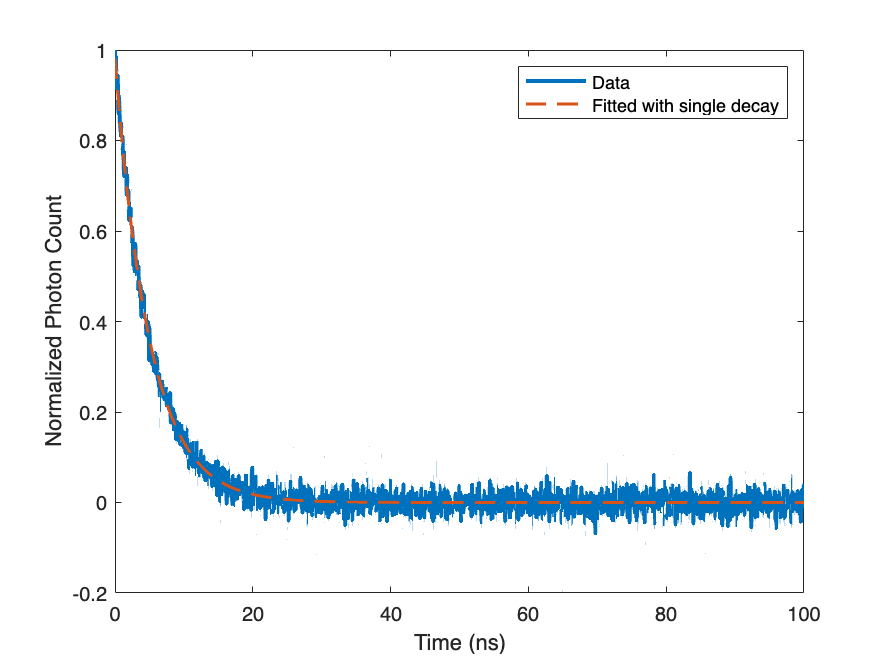


%generate fitted curve
fitted_curve_ls = model(params_ls, time);

%plot data and fit
figure;
hold on;
box on;
plot(time, I, 'LineWidth', 2);
plot(time, fitted_curve_ls, '--', 'LineWidth', 1.5);
xlabel('Time (ns)');
ylabel('Normalized Photon Count');
legend('Data', 'Fitted with single decay');


%show residuals and fitted amplitude
res

res = 0.7577

alpha = params_ls(1)

alpha = 0.9814

### 
$$I(t) = \alpha_1 exp(-t/\tau_1) +\alpha_2 exp(-t/\tau_2)$$


%fit double exponential decay to same data

%fixed lifetimes
tau1 = 5; %ns
tau2 = 1; %ns

%model with 2 amplitudes (one per decay)
model = @(params, t) params(1) * exp(-t / tau1)+params(2) * exp(-t / tau2);

%initial guess for both amplitudes
initial_guess_ls = [1,1];

%fit
[params_ls, res] = lsqcurvefit(model, initial_guess_ls, time, I);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


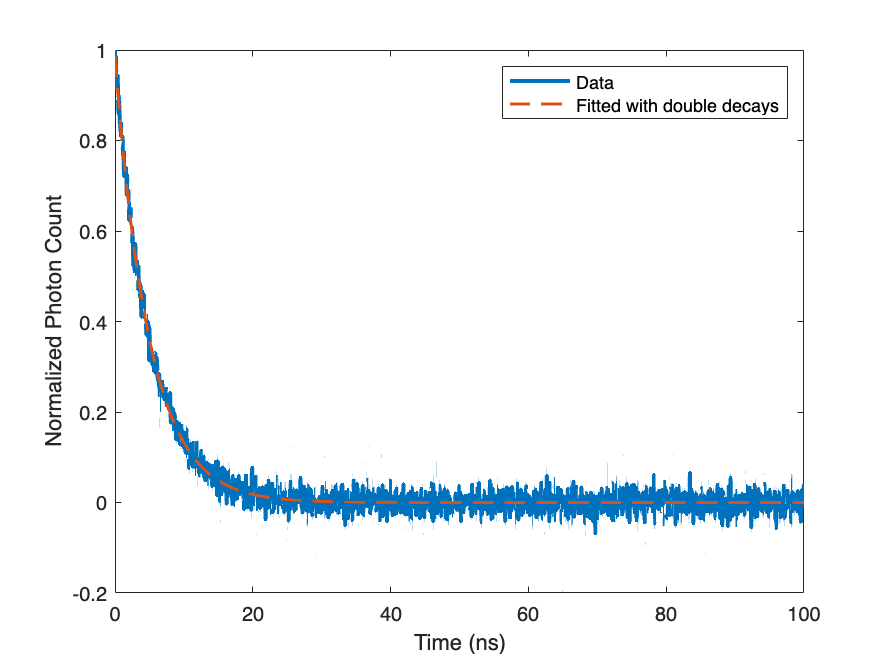


%generate fit curve
fitted_curve_ls = model(params_ls, time);

%plot data and fit
figure;
hold on;
box on;
plot(time, I, 'LineWidth', 2);
plot(time, fitted_curve_ls, '--', 'LineWidth', 1.5);
xlabel('Time (ns)');
ylabel('Normalized Photon Count');
legend('Data', 'Fitted with double decays');


%residuals and fitted amplitudes
res

res = 0.7575

alpha1 = params_ls(1)

alpha1 = 0.9790

alpha2 = params_ls(2)

alpha2 = 0.0071